# Homework 2 (Solutions)

Math 3607, Spring 2022

Tae Eun Kim

Script m-files associated with this document:

- Problem 1: `leapYear.m, isLeapYear.m`

- Problem 2: `coordConvert.m`

## Problem 1 (Leap year)

Before presenting a solution, let me first explain this problem in couple different ways.

#### Version 1

Consider the pseudocode provided in the lecture slides:

Below is a direct translation of the pseudocode:

**Analysis.** The key reason why the code above work is due to the fact that branches of `if`-statement are visited sequentially from top to bottom and only the first branch whose condition evaluates to "true" is executed. One of the best ways to leverage this mechanism is to gradually narrow down the scope of the conditions if possible. See the Venn diagram below which schematically partitions all years into common years (light green) and leap years (light red) according to their numerical characterization.

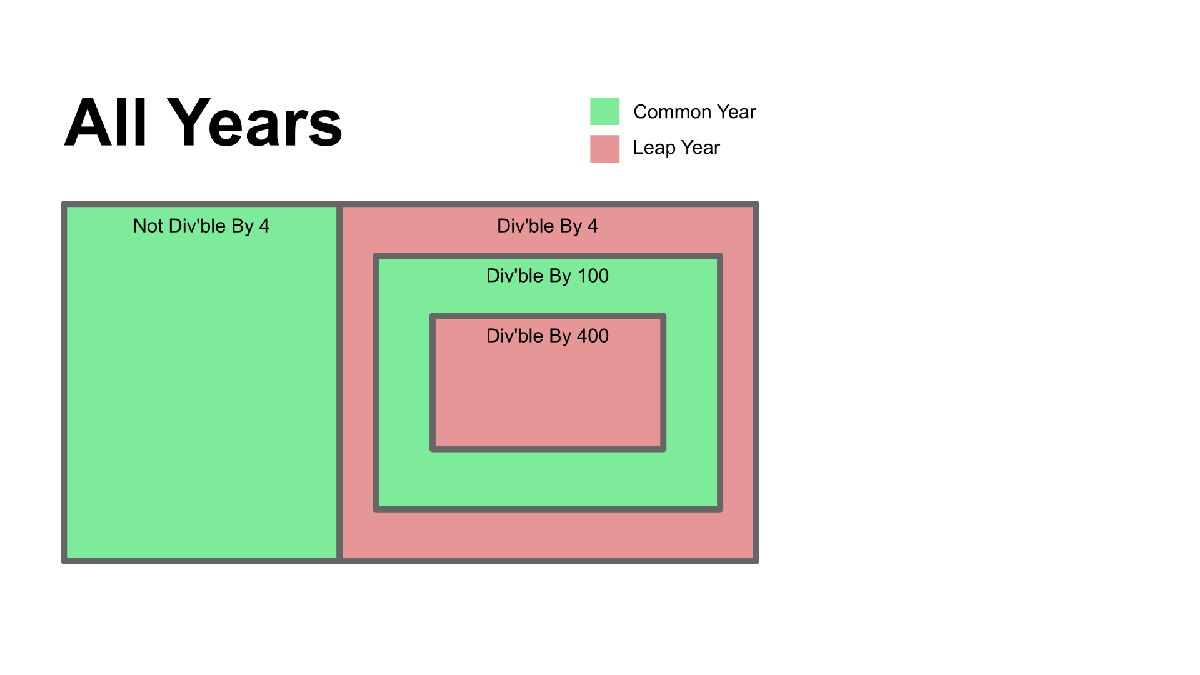

#### Version 2

Alternately, we can utilize the alternate description of leap years given in the homework prompt, that is,

    *"In simpler terms, a non-century year is a leap year if it is divisible by 4; a century year is a leap year if it is divisible by 400."*

and write

In words, this is an example in which different rules are used for century years and non-century years.

#### Version 3

You could piece together multiple conditions characterizing leap years using logical operators.

Here comes a solution.

(a)

type leapYear.m

% script m-file: leapYear.m
% Determines whether a given year is a leap year.

% year = input('Enter year: ');
if mod(year,4)~=0 || ( mod(year,100)==0 && mod(year,400)~=0 )
    fprintf('Year %4d is a common year.\n', year)
else
    fprintf('Year %4d is a leap year.\n', year)
end



(b)

for year = [1900 2000 2020]
    leapYear
end

Year 1900 is a common year.
Year 2000 is a leap year.
Year 2020 is a leap year.


(c) (Optional) For this, I modified the previous script to return a logical output of true if a given year is a leap year. 

type isLeapYear.m

% script m-file: isLeapYear.m
% 
% input: year
% output: l_LY (logical variable)
%          = true  (logical 1) if leap year
%          = false (logical 0) if not.

% year = input('Enter year: ');
if mod(year,4)~=0 || ( mod(year,100)==0 && mod(year,400)~=0 )
    l_LY = false;
else
    l_LY = true;
end



Then we use in a loop to run the script repetitively.

nr_LY = 0;  % number of leap years 
for year = 1900:2022
    isLeapYear;
    if l_LY
        nr_LY = nr_LY + 1;
        disp(year)
    end
end

        1904
        1908
        1912
        1916
        1920
        1924
        1928
        1932
        1936
        1940
        1944
        1948
        1952
        1956
        1960
        1964
        1968
        1972
        1976
        1980
        1984
        1988
        1992
        1996
        2000
        2004
        2008
        2012
        2016
        2020


The number of leap years between 1900 and 2022 is store in 

nr_LY

nr_LY =     30

## Problem 2 (3-D Coordinate Conversion)

(a) Given the relationship between the sets of coordinates, one can derive (or recall from calculus) that


$$\begin{array}{rcl}
\rho & = & \sqrt{x^2 + y^2 + z^2} \\
\tan \theta & = & \frac{y}{x} \\
\cos \phi & = & \frac{z}{\sqrt{x^2 + y^2 + z^2}
\end{array}$$


Note that the last equation, when inverted, yields

$\phi = \arccos \frac{z}{\sqrt{x^2 + y^2 + z^2}} = \arccos \frac{z}{\rho}$,

and since the range of $\arccos$ is precisely $[0, \pi]$, it can be easily coded using the built-in `acos` function. However, since we are require to find $\theta \in [0, 2\pi)$, adjustments are called for. Below is the breakdown of possible scenarios according to the quadrant to which $(x,y)$ belongs. Ignore for now the case in which both $x$ and $y$ are zero.

- [Q1] If $x \ge 0$ and $y \ge 0$ but not both zero, then $\theta = \arctan(y/x)$.

- [Q2] If $x<0$ and $y>0$, then $\theta = \arctan(y/x) + \pi$.

- [Q3] If $x < 0$ and $y \le 0$, then $\theta = \arctan(y/x) + \pi$.

- [Q4] If $x \ge 0$ and $y < 0$, then $\theta = \arctan(y/x) + 2\pi$.

This breakdown is implemented using a for-loop as shown below in part (b).

**Note.** Suppose $y \neq 0$. Mathematically speaking, the fraction $y/x$ is not defined when $x = 0$. But MATLAB produces `Inf `or `-Inf` depending on the sign of $y$. Furthermore, the function `atan` is programmed so that it can handle these special inputs appropriately. However, when $x = y = 0$, MATLAB does the following:

0/0

ans = NaN

atan(0/0)

ans = NaN

So we need to treat this special case separately. How? Think geometry. If $x = y = 0$, then the point $(x,y,z) = (0, 0, z)$, *i.e.*, it lies on the $z$-axis. So

- $\rho = \sqrt{x^2 + y^2 + z^2} =\sqrt{0^2 + 0^2 + z^2}= \vert z \vert$;

- $\phi = \arccos \frac{z}{\vert z \vert} = \arccos (\pm 1)$, which is 0 or $\pi$ depending on the sign of $z$;

- $\theta$ is immaterial and can be any number; we will simply set $\theta = 0$. 

(b) The details are encoded in a script file.

type coordConvert.m

% script m-file: coordConvert.m
% converts cartesian coordinates to spherical coordinates.

% x = input('Enter x: ');
% y = input('Enter y: ');
% z = input('Enter z: ');
fprintf('Given input: (x,y,z) = (%g, %g, %g)\n', x, y, z)
rho = sqrt(x^2 + y^2 + z^2);
phi = acos(z/rho);
if x == 0 && y == 0     % (x,y) = (0,0)
    theta = 0;
elseif x < 0            % 2nd and 3rd quad.
    theta = atan(y/x) + pi;
elseif y < 0            % 4th quad.
    theta = atan(y/x) + 2*pi;
else                    % 1st quad.
    theta = atan(y/x);
end
disp(' ')
fprintf('  rho:   %10.4f\n', rho)
fprintf('  phi:   %10.4f\n', phi)
fprintf('  theta: %10.4f\n', theta)


(c) Let's run the script with the given inputs.

x=1; y=2; z=-2;
coordConvert

Given input: (x,y,z) = (1, 2, -2)
 
  rho:       3.0000
  phi:       2.3005
  theta:     1.1071


x=0; y=-3; z=4;
coordConvert

Given input: (x,y,z) = (0, -3, 4)
 
  rho:       5.0000
  phi:       0.6435
  theta:     4.7124


x=-5; y=-12; z=1;
coordConvert

Given input: (x,y,z) = (-5, -12, 1)
 
  rho:      13.0384
  phi:       1.4940
  theta:     4.3176


x=0; y=0; z=-7;
coordConvert

Given input: (x,y,z) = (0, 0, -7)
 
  rho:       7.0000
  phi:       3.1416
  theta:     0.0000


**Exercise.** As suggested in the lecture slides, do this problem using `atan2` instead of `atan`. Be sure to check out how MATLAB's `atan2` treats the special case of $x=y=0$.

## Problem 3 (Game of 3-stick)

We can use `rand` to simulate picking three sticks with random lengths between 0 and 1.

For this triple to be sides of a triangle, the length of **any** one must not exceed the sum of the other two, that is, all of the following must be true:

- `a < b + c`

- `b < a + c`

- `c < a + b`

Let's simulate a single game.

a = rand();
b = rand();
c = rand();
if (a<b+c) && (b<a+c) && (c<a+b)
    disp('You won!')
else
    disp('You lost.')
end

You lost.


**Note.** At the point in time when this homework assigned, we had not learned about arrays nore MATLAB functions such as `max` or `sort`. Utilizing them, we can somewhat simplify the process of testing whether three given sticks would form a triangle or not, e.g.,

To simulate multiple games, you will embed the code above within a `for`-loop. In addition, we will keep track of the number of games won rather than displaying win/loss messages.

nrWins = 0;
nrGames = 20;
for j = 1:nrGames
    a = rand(); b = rand(); c = rand();
    if (a<b+c) && (b<a+c) && (c<a+b)
        nrWins = nrWins + 1;
    end
end
nrWins

nrWins = 10

nrGames

nrGames = 20

Note the deletion of the else-block since we need not do anything in this context. 

**Final Version. **Now that we know that the script above works with a modest number of games, let's increase it to one million as requested by the problem. In addition, let's format outputs nicely using `fprintf` or `disp`.

%% Solution

nrWins = 0;
nrGames = 1e6;   % one million games
for j = 1:nrGames
    a = rand();
    b = rand();
    c = rand();
    if (a<b+c) && (b<a+c) && (c<a+b)
        nrWins = nrWins + 1;
    end
end
pWin = nrWins/nrGames; % prob. of winning a game
fprintf('Games won:     %8d\n', nrWins)

Games won:       500066


fprintf('Games played:  %8d\n', nrGames)

Games played:   1000000


fprintf('Winning ratio: %8.4f\n', pWin)

Winning ratio:   0.5001


## **Extra: Solving Problem 3 Using New Techniques**

The problem was assigned when we did not know about *arrays*. But by the time this solution is posted, we all do. Since Exam 1 is fast approaching, let's try to work this out using arrays for practice. 

**Step 1.** Simulate multiple games using `rand` function.

format short
nrGames = 20;
sticks = rand(3, nrGames)

sticks =     0.5655    0.3566    0.1627    0.8257    0.2893    0.1054    0.5194    0.5121    0.5129    0.4037    0.6353    0.4347    0.7202    0.8916    0.1119    0.2773    0.0699    0.8864    0.5967    0.8537
    0.5280    0.0555    0.2825    0.5447    0.3527    0.0314    0.4694    0.4005    0.9337    0.1542    0.8536    0.5510    0.4617    0.2793    0.2499    0.3022    0.7349    0.7966    0.1352    0.5400
    0.3910    0.2246    0.2000    0.6724    0.6841    0.1273    0.5987    0.9541    0.9499    0.1219    0.9330    0.1061    0.5992    0.2552    0.6972    0.4071    0.3055    0.3032    0.8535    0.5767


Each column corresponds to a single game. The matrix `sticks` holds the information of 20 games.

**Step 2.** Generate an auxiliary matrix incorporating the "triangle" conditions. 

I will create an auxiliary matrix `A` (for analysis) whose $j$th columns contain the following information:

- `A(1,j) = -sticks(1,j) + sticks(2,j) + sticks(3,j)`

- `A(2,j) =  sticks(1,j) - sticks(2,j) + sticks(3,j)`

- `A(3,j) =  sticks(1,j) + sticks(2,j) - sticks(3,j)`

In this setup, the $j$th game is won if and only if all entries of the $j$th column of `A` are positive. 

A = zeros(size(sticks));
A(1,:) = -sticks(1,:) + sticks(2,:) + sticks(3,:);
A(2,:) =  sticks(1,:) - sticks(2,:) + sticks(3,:);
A(3,:) =  sticks(1,:) + sticks(2,:) - sticks(3,:);
A

A =     0.3535   -0.0765    0.3198    0.3914    0.7474    0.0533    0.5487    0.8424    1.3706   -0.1276    1.1513    0.2224    0.3406   -0.3571    0.8352    0.4320    0.9706    0.2134    0.3920    0.2630
    0.4285    0.5257    0.0802    0.9534    0.6207    0.2012    0.6487    1.0657    0.5292    0.3714    0.7148   -0.0102    0.8577    0.8675    0.5592    0.3822   -0.3595    0.3930    1.3150    0.8904
    0.7025    0.1874    0.2452    0.6980   -0.0421    0.0095    0.3901   -0.0415    0.4967    0.4361    0.5558    0.8797    0.5827    0.9157   -0.3353    0.1724    0.4993    1.3798   -0.1217    0.8170


**    Sidenote. **The matrix `A` can be constructed by a single statement

    This is a triumphant moment in which the understanding of matrix multiplication shines in progamming! (Make sure you understand why this works!)

Now, I will replace positive entries of `A` by 1 and non-positive (that is, less than or equal to zero) entries by 0.

A(  A>0 ) = 1;   % same as A( find( A>0) ) = 1, but more efficient
A( A<=0 ) = 0;   % same as A( find(A<=0) ) = 0, but more efficient
A

A =      1     0     1     1     1     1     1     1     1     0     1     1     1     0     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     0     1     1     1
     1     1     1     1     0     1     1     0     1     1     1     1     1     1     0     1     1     1     0     1


**Step 3.** Identify the games won.

Finally, generate a row vector by sum all elements of `A` along columns:

sumA = sum(A)

sumA =      3     2     3     3     2     3     3     2     3     2     3     2     3     2     2     3     2     3     2     3


The elements that are equal to 3 correspond to the games won!

**Full script (Vectorized).**

Let's put all together.

nrGames = 1e6;
sticks = rand(3, nrGames);
A = [-1 1 1; 1 -1 1; 1 1 -1] * sticks;
A( A >0 ) = 1;
A( A<=0 ) = 0;
sumA = sum(A);
nrWins = length(find(sumA==3));
pWin = nrWins/nrGames; % prob. of winning a game
fprintf('Games won:     %8d\n', nrWins)

Games won:       499457


fprintf('Games played:  %8d\n', nrGames)

Games played:   1000000


fprintf('Winning ratio: %8.4f\n', pWin)

Winning ratio:   0.4995


## Problem 4 (Gap of 10)

The key point of this problem lies in simulating the tossing of a biased coin with the following probability profile: $P(H) = 1/4$ (heads) and $P(T) = 3/4$ (tails). Let's use 0 for tails and 1 for heads. I will show couple ways.

**Using **`randi:`

toss = randi([0 3]);
if toss > 0
    toss = 1;
end
toss

toss = 1

**Using **`rand:`

toss = floor( rand() + 0.25 )

toss = 0

Why does it work? The expression `rand() + 0.25`  generates a number in $(0.25, 1.25)$ with equal likelihood. So numbers in the interval $(0.25, 1)$ are three times more likely to appear than those from $[1, 1.25)$. The `floor` function maps numbers in $(0.25, 1)$ to 0 and those in $[1, 1.25)$ to 1, successfully simulating the tossing of a bias coin with the given description. 

It is not known in advance how many tosses are needed until the gap reached 10. So use a `while`-loop:

nTosses = 0;  % number of tosses
nHeads = 0;   % number of heads
nTails = 0;   % number of tails
while abs(nHeads-nTails) < 10
    toss = floor( rand() + 0.25 );
    if toss == 0
        nTails = nTails + 1;
    else
        nHeads = nHeads + 1;
    end
    nTosses = nTosses + 1;
end
fprintf('The gap reached 10 with %d tosses.\n', nTosses)

The gap reached 10 with 18 tosses.


Finally, we want to repeat the simulation multiple times and to monitor how many tosses are needed till the gap reaches 10. We will need an additional (outer loop) to embrace the `while`-loop written above. For example:

%% Solution

nGames = 10; % number of games played
result = zeros(nGames, 1); 
% initialize a vector to record the number of tosses
% to reach the gap of 10.

for j = 1:nGames
    nTosses = 0;  % number of tosses
    nHeads = 0;   % number of heads
    nTails = 0;   % number of tails
    while abs(nHeads-nTails) < 10
        toss = floor( rand() + 0.25 );
        if toss == 0
            nTails = nTails + 1;
        else
            nHeads = nHeads + 1;
        end
        nTosses = nTosses + 1;
    end
    fprintf('Simulation %2d done in %2d tosses.\n', j, nTosses)
    result(j) = nTosses;
end

Simulation  1 done in 14 tosses.
Simulation  2 done in 26 tosses.
Simulation  3 done in 10 tosses.
Simulation  4 done in 14 tosses.
Simulation  5 done in 22 tosses.
Simulation  6 done in 12 tosses.
Simulation  7 done in 22 tosses.
Simulation  8 done in 10 tosses.
Simulation  9 done in 20 tosses.
Simulation 10 done in 18 tosses.


Since we stored the results in an array `result`, we can easily find the average number of tosses till the gap reaches 10:

mean(result)

ans = 16.8000

That is, on average, it took 19 tosses till the gap reached 10.

## Problem 5 (Convergence of Sequences)

We will take the value of `pi` stored in MATLAB as the true value of $\pi$. As a prep work, suppose that `n` is given. We will concentrate first on calculating $a_n$ and $b_n$. Using a `for`-loop, we can form these terms as below:

format long g
n = 10;
a_n = 0; b_n = 0;
for k = 0:n
    a_n = a_n + 6/sqrt(3)*(-1/3)^k / (2*k+1);
    b_n = b_n + 16/5*(-1/25)^k / (2*k+1) - 4/239*(-1/239^2)^k / (2*k+1);
end
a_n

a_n =           3.14159330450308

b_n

b_n =           3.14159265358979

As the last lines show, with only $n = 10$, they are already quite close to $\pi$. 

Now that the key part of the problem has been solve, let's design an outer loop which calculates terms $a_0, a_1, \ldots$ until it is close enough to $\pi$. (One may avoid the use of the inner for-loop, but I will present this slightly verbose version for the sake of instruction.) The given *tolerance* is $10^{-6}$. Though the problem only asks to print out $a_0, a_1, \ldots$, I will print out some more information.

%% Solution

tol = 1e-6;
nMax = 100;    % maximum number of iterations
n = 0;
while n == 0 || (errAbs > tol && n <= nMax)
    if n == 0
        fprintf('%2s %16s %16s\n', 'n', 'a_n', '|a_n - pi|');
        fprintf('%36s', repmat('-', 1, 36))
    end
    a = 0;
    for k = 0:n
        a = a + (-1/3)^k / (2*k+1);
    end
    a = 6/sqrt(3)*a;   % since 6/sqrt(3) is a common factor.
    errAbs = abs(a - pi);
    fprintf('%2d %16.8f %16.8e\n', n, a, errAbs)
    n = n + 1;
end

 n              a_n       |a_n - pi|


------------------------------------

 0       3.46410162   3.22508962e-01
 1       3.07920144   6.23912179e-02
 2       3.15618147   1.45888180e-02
 3       3.13785289   3.73976199e-03
 4       3.14260475   1.01209207e-03
 5       3.14130879   2.83868127e-04
 6       3.14167431   8.16591090e-05
 7       3.14156872   2.39376480e-05
 8       3.14159977   7.12022171e-06
 9       3.14159051   2.14265171e-06
10       3.14159330   6.50913289e-07


**Note.** Before the beginning of the `while`-loop, the variable `errAbs` was not initialized and so the loop would not be initated if it were not for `n==0` preceding `(errAbs ... )`. An alternate method that is commonly used is to begin with

We handle $b_n$'s in the same fashion.

%% Solution

tol = 1e-6;
nMax = 100;    % maximum number of iterations
n = 0;
while n == 0 || (errAbs > tol && n <= nMax)
    if n == 0
        fprintf('%2s %16s %16s\n', 'n', 'b_n', '|b_n - pi|');
        fprintf('%36s', repmat('-', 1, 36))
    end    
    b1 = 0; b2 = 0;
    for k = 0:n
        b1 = b1 + (-1/25)^k/(2*k+1);
        b2 = b2 + (-1/239^2)^k/(2*k+1);
    end
    b = 16/5*b1 - 4/239*b2;
    errAbs = abs(b - pi);
    fprintf('%2d %16.8f %16.8e\n', n, b, errAbs)
    n = n + 1;
end

 n              b_n       |b_n - pi|


------------------------------------

 0       3.18326360   4.16709447e-02
 1       3.14059703   9.95624264e-04
 2       3.14162103   2.83757352e-05
 3       3.14159177   8.81407615e-07


The two numerical experiments provide an evidence that the sequence $b_n$ may converge to $\pi$ much quicker than $a_n$. 